# `HomeWork n.1 2021/22`

### `Madonna Enrico 0124002279`

**TRACCIA HOMEWORK**

Calcolate due numeri interi $p$ e $q$  che sono, rispettivamente, il numero di caratteri del vostro nome e il numero di caratteri del vostro  cognome. Usate questi due numeri per creare la seguente funzione:


$$e^{-x} \cdot (cos(\frac {p \cdot x}{2}-\pi/2))^2 +  \frac {q}{1+2x^2}cos(2x)-3$$


Tale funzione è la vostra **funzione di riferimento**. Scegliete un certo intervallo $[a,b]$ in modo che la vostra funzione di riferimento abbia **esattamente** 5 zeri, 2 minimi e 2 massimi in tale intervallo.

**Punto 1: definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete **`funrif.`

`Inizio definendo ``p = 6 ``e ``q = 7``  poichè il nome Enrico è composto da 6 caratteri e il cognome Madonna ne ha 7.`

`Non mi resta altro che scrivere la mia ``funrif`

funrif = @(x) exp(-x).*(cos(6*x/2-pi/2)).^2+(7./(1+2*x.^2).*cos(2*x)-3);%questa è la mia funzione di riferimento

`Ora visualizzo il grafico della funzione:`

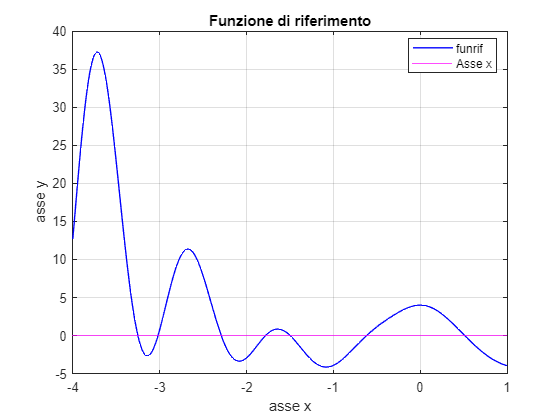

format long %Imposto tutti i numeri in formato long, come richiesto

%Osservo la mia funzione in un intervallo abbastanza ampio per ricercare i punti di interesse
figure(1) 
fplot(funrif,[-4,1],'color','b')
axis([-4 1 -5 40]) 
hold on 
grid on 
yline(0,'-','color','m'); %Evidenzio l'asse delle x
legend({'funrif','Asse x',},'Location','best','AutoUpdate','off') %Visualizzo la legenda

%Aggiungo il titolo del grafico e nomino gli assi
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Funzione di riferimento",'FontName','Arial')

**Punto 2:** **visualizzate il grafico della funzione di riferimento in **$[a,b]$**, specificando espicitamente quale intervallo avete scelto e indicando sul grafico (comando **`text`**) gli estremi dell'intervallo scelto, i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *****punto di minimo 1*****), il secondo valore minimo e l'ascissa del secondo minimo (detta *****punto di minimo 2*****), il primo valore massimo e l'ascissa del primo massimo (detta *****punto di massimo 1*****), il secondo valore massimo e l'ascissa del secondo massimo (detta *****punto di massimo 2).***

Ho deciso di scegliere un intervallo* [a,b]* tale che* a= -2.35 e b=0.8*  così che la funzione di riferimento abbia esattamente 5 zeri, 2 minimi e 2 massimi.

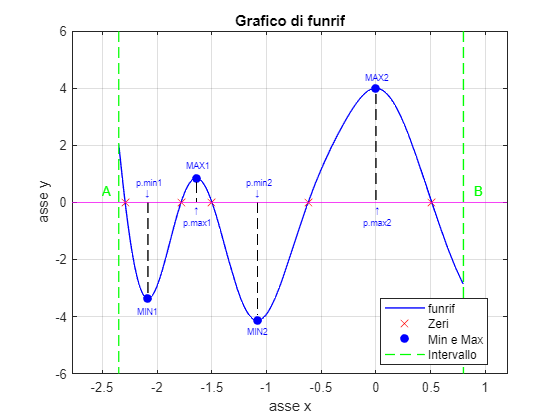

figure(2)
%imposto l'intervallo
a=-2.35;
b= 0.8;
%imposto il grafico
fplot(funrif,[a,b],'color','b')
axis([-2.77 1.2 -6 6]) 
hold on 
grid on 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Grafico di funrif",'FontName','Arial')

%Indico gli zeri, i minimi e i massimi
plot([-2.29 -1.78 -1.5 -0.62 0.51],[0 0 0 0 0],'x','markersize',8,'color','r')
plot([-2.0835 -1.641 -1.0835 0 ], [-3.3665 0.85 -4.1391 4 ],'o','color','b','MarkerFaceColor','b')

%Indico le ascisse dei punti di minimo e di massimo
text(-2.115,0.3,'\downarrow', "Color", 'b',"FontSize",6.5);
text(-2.19,0.7,'p.min1', "Color", 'b',"FontSize",6.5); 
text(-2.18,-3.8,'MIN1', "Color", 'b',"FontSize",6.5);
text(-1.11,0.3,'\downarrow', "Color", 'b',"FontSize",6.5);
text(-1.19,0.7,'p.min2', "Color", 'b',"FontSize",6.5);
text(-1.18,-4.5,'MIN2', "Color", 'b',"FontSize",6.5);

text(-1.67,-0.3,'\uparrow', "Color", 'b',"FontSize",6.5);
text(-1.76,-0.7,'p.max1', "Color", 'b',"FontSize",6.5);
text(-1.74,1.3,'MAX1', "Color", 'b',"FontSize",6.5);
text(-0.02,-0.3,'\uparrow', "Color", 'b',"FontSize",6.5);
text(-0.12,-0.7,'p.max2', "Color", 'b',"FontSize",6.5);
text(-0.1,4.4,'MAX2', "Color", 'b',"FontSize",6.5);

%Indico i miei estremi a e b
plot([a,a], [6,-6], '--','color','g',LineWidth=1)
plot([b,b], [6,-6], '--','color','g',LineWidth=1)
text(a-0.15,0.4,'A','color','g')
text(b+0.1,0.4,'B','color','g')
legend({'funrif','Zeri','Min e Max','Intervallo',},'Location','best','AutoUpdate','off')

%proiezione punti di min e max
plot([-2.0835, -2.0835], [0,-3.3], '--','color','k')
plot([-1.0835,-1.0835], [0,-3.95], '--','color','k')

plot([-1.641,-1.641],[0.7,0],'--','color','k')
plot([0,0],[3.8,0],'--','color','k')

yline(0,'-','color','m');

**Punto 3:usate la function Matlab **`fzero`** per determinare i 5 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte.**

Uso la function `fzero` per determinare i 5 zeri della mia funrif che considero come i miei zeri esatti.

Ho deciso di implementare un ciclo for che ad ogni iterazione calcola l'n-esimo zero e lo salva in istanza di un array che chiamo zero_esatto

zero_esatto=[0 0 0 0 0];%creo l'array
zero_approssimati=[-2.29,-1.78,-1.50,-0.60,0.51];
%inizio il ciclo
for i=1:5
    zero_esatto(i)=fzero(funrif,zero_approssimati(i));
    fprintf('• Zero Numero %d = %.15f\n\n',i,zero_esatto(i))
end

• Zero Numero 1 = -2.291664846666567

• Zero Numero 2 = -1.781165916088720

• Zero Numero 3 = -1.497929721343405

• Zero Numero 4 = -0.619351752191931

• Zero Numero 5 = 0.510816602581262



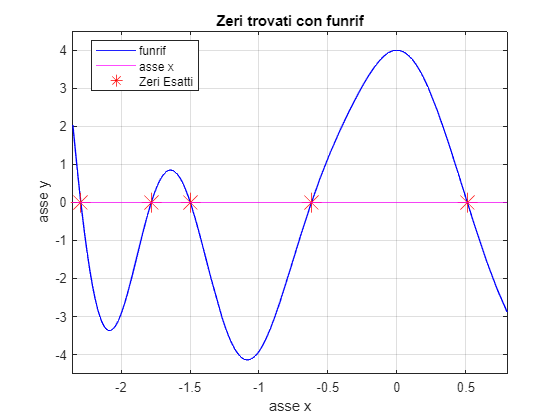

figure(3);
%Inizializzo il grafico
fplot(funrif,[a,b],'color','b') 
axis([a b -4.5 4.5]) 
hold on
grid on 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Zeri trovati con funrif",'FontName','Arial')
yline(0,'-','color','m');

%Indico gli zeri che ho trovato attraverso la funzione funrif
for i=1:5
plot((zero_esatto(i)),(0),'*','markersize',15,'color','red')
end
legend({'funrif','asse x','Zeri Esatti'},'Location','best')

**Punto 4: determinate un'approssimazione dei 5 zeri, usando il metodo di bisezione (nostra function **`bisezione`**) per lo zero più piccolo, il metodo delle Secanti (nostra function **`Secanti`**) per il secondo e terzo zero  e il metodo di Newton (nostra function **`Newton`**) per il quarto e il quinto zero (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette.**

**Metodo di bisezione **

Uso il metodo di bisezione per determinare un'approssimazione del primo zero (quello più piccolo).

delta_ass=1e-6; %imposto la stima del massimo errore assoluto richiesto sul risultato
zero_bisezione=bisezione(funrif,-2.29166485,-2.29166484,delta_ass) 

zero_bisezione =   -2.291664845000000


**Metodo delle secanti**

Uso il metodo delle secanti per determinare un'approssimazione del secondo e terzo zero.

kmax=10; %imposto il numero massimo di iterazioni permesse
zero_secanti1=Secanti(funrif,-1.79,-1.78,delta_ass,kmax)

zero_secanti1 =   -1.781165311740114


zero_secanti2=Secanti(funrif,-1.51,-1.49,delta_ass,kmax)

zero_secanti2 =   -1.497929725735099


**Metodo di newton**

Uso il metodo di newton per determinare un'approssimazione del quarto e quinto zero.

Per implementare il metodo di Newton ho calcolato attraverso *funtool* la derivata prima della funzione di riferimento. 

derivataprima = @(x) -cos(3.*x - pi./2).^2.*exp(-x) - (14.*sin(2.*x))./(2.*x.^2 + 1) - (28.*x.*cos(2.*x))./(2.*x.^2 + 1).^2 - 6.*cos(3.*x - pi./2).*sin(3.*x - pi./2).*exp(-x);%scrivo la derivata prima
%Adesso posso calcolare i restanti zeri
zero_newton1= Newton(funrif,derivataprima,-0.62,delta_ass,kmax)

zero_newton1 =   -0.619352037209224


zero_newton2= Newton(funrif,derivataprima,0.5,delta_ass,kmax)

zero_newton2 =    0.510816602553810


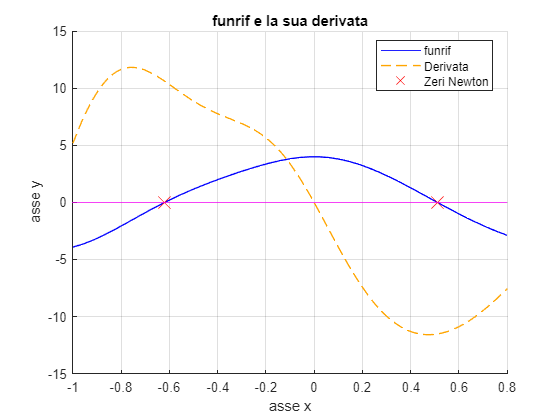

figure(4);
%Inizializzo il grafico
hold on
fplot(funrif,[-1,0.8],'color','b')
fplot(derivataprima,[-1,0.8],"--","LineWidth",1,'Color','#FFA500') 
grid on 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("funrif e la sua derivata",'FontName','Arial')
plot(zero_newton1,(0),'x','markersize',13,'color','r')
plot(zero_newton2,(0),'x','markersize',13,'color','r')
legend({'funrif','Derivata','Zeri Newton'},'Location','best','AutoUpdate','off')
yline(0,'-','color','m');

Visualizzo gli zeri che ho trovato attraverso il metodo di newton e funrif con la sua derivata.

**Punto 5: Considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con le Secanti), sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con Newton) e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei cinque zeri.**

**ERRORI ASSOLUTI**

%Calcolo l'errore assoluto del primo punto (metodo bisezione)
errass_bisezione= abs(zero_bisezione-zero_esatto(1))

errass_bisezione =      1.666566440405859e-09


if errass_bisezione<=delta_ass%confronto errore assoluto e accuratezza
    fprintf('Soluzione dell''approssimazione di bisezione minore dell accuratezza richiesta.')
else
    fprintf('Soluzione dell''approssimazione di bisezione maggiore dell accuratezza richiesta.')
end

Soluzione dell'approssimazione di bisezione minore dell accuratezza richiesta.

%Calcolo l'errore assoluto del secondo punto (metodo secanti)
errass_secanti1=abs(zero_secanti1 - zero_esatto(2))

errass_secanti1 =      6.043486060480774e-07


if errass_secanti1<=delta_ass %confronto errore assoluto e accuratezza
    fprintf('Soluzione dell''approssimazione delle secanti minore dell accuratezza richiesta.')
else
    fprintf('Soluzione dell''approssimazione delle secanti maggiore dell accuratezza richiesta.')
end

Soluzione dell'approssimazione delle secanti minore dell accuratezza richiesta.

%Calcolo l'errore assoluto del terzo punto (metodo secanti)
errass_secanti2=abs(zero_secanti2 - zero_esatto(3))

errass_secanti2 =      4.391694341521202e-09


if errass_secanti2<=delta_ass %confronto errore assoluto e accuratezza
    fprintf('Soluzione dell''approssimazione delle secanti minore dell accuratezza richiesta.')
else
    fprintf('Soluzione dell''approssimazione delle secanti maggiore dell accuratezza richiesta.')
end

Soluzione dell'approssimazione delle secanti minore dell accuratezza richiesta.

%Calcolo l'errore assoluto del quarto punto (metodo Newton)
errass_newton1=abs(zero_newton1 - zero_esatto(4))

errass_newton1 =      2.850172932111761e-07


if errass_newton1<=delta_ass %confronto errore assoluto e accuratezza
    fprintf('Soluzione dell''approssimazione di Newton minore dell accuratezza richiesta.')
else
    fprintf('Soluzione dell''approssimazione di Newton maggiore dell accuratezza richiesta.')
end

Soluzione dell'approssimazione di Newton minore dell accuratezza richiesta.

%Calcolo l'errore assoluto del quinto punto (metodo Newton)
errass_newton2=abs(zero_newton2 -zero_esatto(5))

errass_newton2 =      2.745237370760378e-11


if errass_newton2<=delta_ass %confronto errore assoluto e accuratezza
    fprintf('Soluzione dell''approssimazione di Newton minore dell accuratezza richiesta.')
else
    fprintf('Soluzione dell''approssimazione di Newton maggiore dell accuratezza richiesta.')
end

Soluzione dell'approssimazione di Newton minore dell accuratezza richiesta.

**RESIDUI**

residuo_bisezione=abs(funrif(zero_bisezione))%calcolo residuo primo zero

residuo_bisezione =      5.303891148500384e-08


L'ordine di grandezza del residuo dell'approssimazione del metodo delle di bisezione per il primo zero è simile all'accuratezza richiesta di 10^-6, dunque il problema è ben condizionato.

residuo_secanti1=abs(funrif(zero_secanti1))%calcolo residuo secondo zero

residuo_secanti1 =      6.936030028992235e-06


L'ordine di grandezza del residuo dell'approssimazione del metodo delle delle secanti per il secondo zero è uguale all'accuratezza richiesta di 10^-6, dunque il problema è ben condizionato.

residuo_secanti2=abs(funrif(zero_secanti2))%calcolo residuo terzo zero

residuo_secanti2 =      4.809149434237270e-08


L'ordine di grandezza del residuo dell'approssimazione del metodo delle delle secanti per il terzo zero è simile all'accuratezza richiesta di 10^-6, dunque il problema è ben condizionato.

residuo_newton1=abs(funrif(zero_newton1))%calcolo residuo quarto zero

residuo_newton1 =      3.026811995043843e-06


L'ordine di grandezza del residuo dell'approssimazione del metodo dei Newton per il quarto zero è uguale all'accuratezza richiesta di 10^-6, dunque il problema è ben condizionato.

residuo_newton2=abs(funrif(zero_newton2))%calcolo residuo quinto zero

residuo_newton2 =      3.165605555466300e-10


L'ordine di grandezza del residuo dell'approssimazione del metodo di Newton per il quinto zero è simile all'accuratezza richiesta di 10^-6, dunque il problema è ben condizionato.

**INDICI DI CONDIZIONAMENTO**

Indice condizionamento bisezione

indice_condizionamento_bisezione=1/abs(derivataprima(zero_esatto(1)))%calcolo indice di condizionamento del primo zero

indice_condizionamento_bisezione =    0.031421571193125


Indice condizionamento bisezione

indice_condizionamento_secanti1=1/abs(derivataprima(zero_esatto(2)))%calcolo indice di condizionamento del secondo zero

indice_condizionamento_secanti1 =    0.087131633206913


indice_condizionamento_secanti2=1/abs(derivataprima(zero_esatto(3)))%calcolo indice di condizionamento del terzo zero

indice_condizionamento_secanti2 =    0.091319563995643


Indice condizionamento Newton

indice_condizionamento_newton1=1/abs(derivataprima(zero_esatto(4)))%calcolo indice di condizionamento del quarto zero

indice_condizionamento_newton1 =    0.094164206084192


indice_condizionamento_newton2=1/abs(derivataprima(zero_esatto(5)))%calcolo indice di condizionamento del quinto zero

indice_condizionamento_newton2 =    0.086721051698875


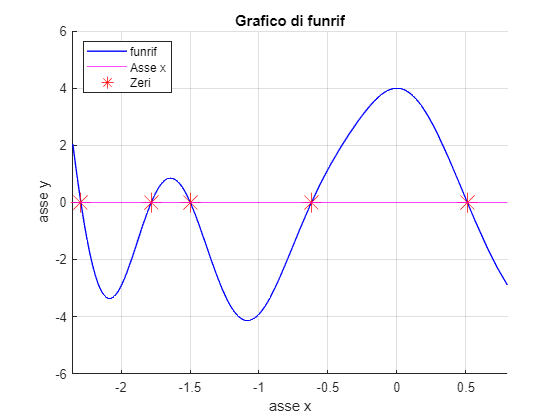

figure(5)
hold on 
grid on 
fplot(funrif,[a,b],'color','b')

axis([a b -6 6])

xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Grafico di funrif",'FontName','Arial')
yline(0,'-','color','m') 

for i=1:5
plot((zero_esatto(i)),(0),'*','markersize',15,'color','red')
end
legend({'funrif','Asse x','Zeri'},'Location','northwest')

Osservando il grafico si può notare che la funzione, quando interseca l'asse delle x, non è schiacciata, dunque intuisco che il problema della ricerca dello zero della funzione di riferimento è ben condizionato. E come mi aspettavo infatti, ho trovato degli indici di condizionamento piccoli.

**Punto 6: osservando il grafico della vostra funzione di riferimento nell'intervallo **$[a,b]$**e della bisettrice, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function **`PFisso (suggerimento: `**usate opportunamente**` fzero)`**, calcolate una approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, cioè più vicino ad **$a$**, e determinate il residuo; dite se il metodo del punto fisso convergerebbe a tale punto fisso.**

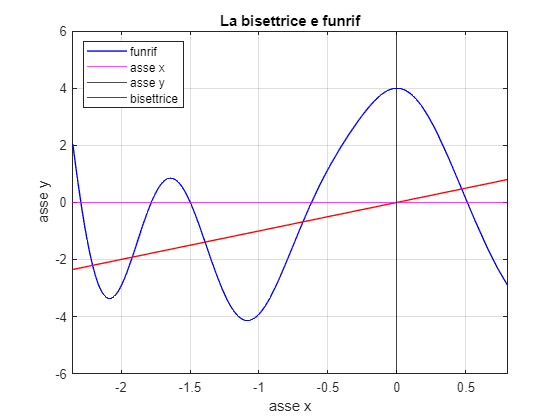

figure(6)
fplot(funrif,[a,b],'color','b')
axis([a b -6 6]) 
hold on 
grid on 
yline(0,'-','color','m') 
xline(0,'-','color','k') 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("La bisettrice e funrif",'FontName','Arial')

%creo la bisettrice
bisettrice=linspace (a,b,2);
plot(bisettrice,bisettrice,'color','r')

legend({'funrif','asse x','asse y','bisettrice'},'Location','northwest','AutoUpdate','off')

Dal grafico posso osservare che la bisettrice interseca la funzione nell'intervallo [a, b] per ben 5 volte, quindi ho 5 punti fissi.

Per calcolare un approssimazione del primo punto fisso (quello più vicino all'estremo *a* del mio intervallo) usando la funzione *fzero*, devo prendere in considerazione la funzione *funrif(x)-x=0 *e passare un'approssimazione iniziale (in questo caso specifico, la mia variabile* 'a'* che ho considerato come inizio dell'intrvallo va bene).

approssimazione_pfisso=fzero(@(x)funrif(x)-x,a)

approssimazione_pfisso =   -2.206327244646405


Calcolo il residuo:

residuo_pfisso=abs(funrif(approssimazione_pfisso)-approssimazione_pfisso)

residuo_pfisso =      1.332267629550188e-15


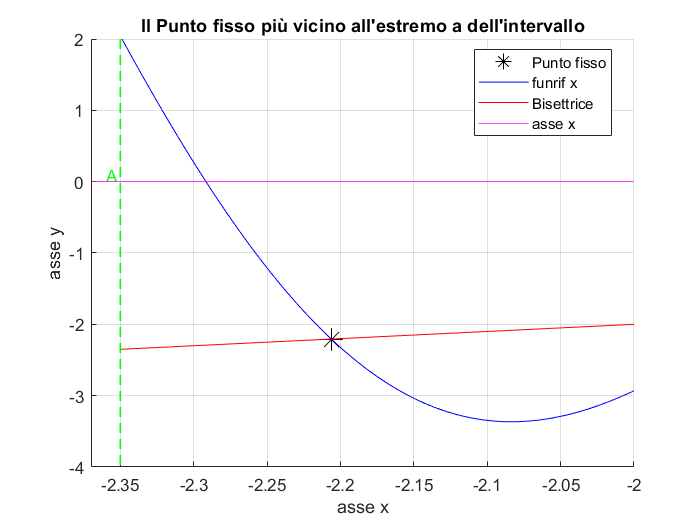

figure(7)
hold on
grid on
axis([a-0.02 -2 -4 2])
plot(approssimazione_pfisso,approssimazione_pfisso,'*','markersize',13,'color','k')
fplot(funrif,[a,b],'color','b')
plot(bisettrice,bisettrice,'color','r')
yline(0,'-','color','m') 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Il Punto fisso più vicino all'estremo a dell'intervallo",'FontName','Arial')
plot([a,a], [6,-6], '--','color','g',LineWidth=1)
text(a-0.01,0.1,'A','color','g')
legend({'Punto fisso','funrif x','Bisettrice','asse x'},'Location','best','AutoUpdate','off')

c=abs(derivataprima(approssimazione_pfisso))%calcolo la costante di proporzionalità c che mi da informazioni sulla convergenza del metodo del punto fisso

c =   19.344304067053486


Poichè il valore assoluto della derivata prima calcolata nell'approssimazione del punto fisso da me trovato è maggiore di 1, posso dire che il metodo del punto fisso divergerebbe.

**Punto 7:usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in **$[a,b]$**, con quattro chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo).**

Calcolo i minimi con *fminbnd*

min1=fminbnd(funrif,-2.3,-2,optimset('TolX',1e-10))%trovo il primo minimo

min1 =   -2.083546548960639


min2=fminbnd(funrif,-1.3,-1,optimset('TolX',1e-10))%trovo il secondo minimo

min2 =   -1.083347868918432


Poichè *fminbnd* calcola il minimo di una funzione, per ottenere il massimo mi basta passare come argomento l'inversa di funrif

inversa_funrif=@(x) -funrif(x);%trovo la funzione inversa
max1=fminbnd(inversa_funrif,-1.9,-1.5,optimset('TolX',1e-10))%trovo il primo massimo

max1 =   -1.641304257810645


max2=fminbnd(inversa_funrif,-0.5,0.5,optimset('TolX',1e-10))%trovo il secondo massimo

max2 =      1.042595009403680e-10


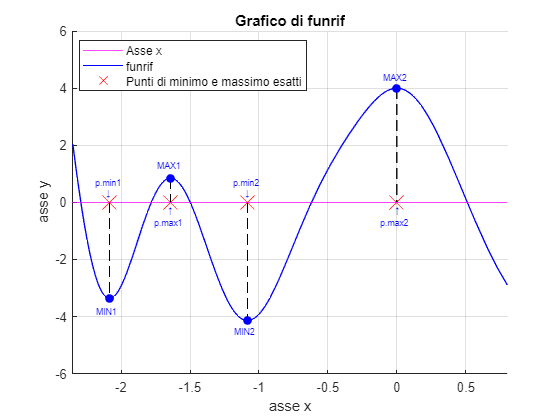


figure(8)
hold on
yline(0,'-','color','m') 
fplot(funrif,[a,b],'color','b')
plot([min1 max1 min2 max2],[0 0 0 0],'x','markersize',15,'color','red');
legend({'Asse x','funrif','Punti di minimo e massimo esatti'},'Location','best','AutoUpdate','off')
axis([a b -6 6])  
grid on 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Grafico di funrif",'FontName','Arial')

%proiezione punti di min e max
plot([min1, min1], [0,funrif(min1)], '--','color','k')
plot([min2,min2], [0,funrif(min2)], '--','color','k')

plot([max1,max1],[funrif(max1),0],'--','color','k')
plot([max2,max2],[funrif(max2),0],'--','color','k')

%Indico le ascisse dei punti di minimo e di massimo
text(-2.115,0.3,'\downarrow', "Color", 'b',"FontSize",6.5);
text(-2.19,0.7,'p.min1', "Color", 'b',"FontSize",6.5);
text(-2.18,-3.8,'MIN1', "Color", 'b',"FontSize",6.5);
text(-1.11,0.3,'\downarrow', "Color", 'b',"FontSize",6.5);
text(-1.19,0.7,'p.min2', "Color", 'b',"FontSize",6.5);
text(-1.18,-4.5,'MIN2', "Color", 'b',"FontSize",6.5);

text(-1.67,-0.3,'\uparrow', "Color", 'b',"FontSize",6.5);
text(-1.76,-0.7,'p.max1', "Color", 'b',"FontSize",6.5);
text(-1.74,1.3,'MAX1', "Color", 'b',"FontSize",6.5);
text(-0.02,-0.3,'\uparrow', "Color", 'b',"FontSize",6.5);
text(-0.12,-0.7,'p.max2', "Color", 'b',"FontSize",6.5);
text(-0.1,4.4,'MAX2', "Color", 'b',"FontSize",6.5);

%indico i massimi e i minimi
plot([min1 max1 min2 max2], [funrif(min1) funrif(max1) funrif(min2) funrif(max2) ],'o','color','b','MarkerFaceColor','b')

**Punto 8: verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione sia il grafico della sua derivata (può essere utile usare anche la scalatura della finestra grafica data dal comando **`axis([xmin xmax ymin ymax])`** ), e usando la **`fzero`** per calcolare tutti gli zeri della derivata; commentate i risultati ottenuti.**

Dal teorema di Fermat so che l'annullamento della derivata prima di una funzione derivabile in un punto $x_0$ sia un punto di massimo o minimo relativo o assoluto per la funzione. Dunque posso calcolare gli zeri della derivata e aspettarmi che coincidano con i minini e i massimi della mia funrif.

zeroder1=fzero(derivataprima,-2.3) %calcolo il primo zero della derivata

zeroder1 =   -2.083546548690336


zeroder2=fzero(derivataprima,-1.6)%calcolo il terzosecondo zero della derivata

zeroder2 =   -1.641304257948854


zeroder3=fzero(derivataprima,-1)%calcolo il terzo zero della derivata

zeroder3 =   -1.083347868890650


zeroder4=fzero(derivataprima,0)%calcolo il quarto zero della derivata

zeroder4 =      1.258326505592718e-17


I risultati ottenuti differiscono per le ultime cifre decimali rispetto ai risultati dei minimi e dei massimi ottenuti con la funrif, questo dipende dall'accuratezza della funzione. Nonostante ciò posso affermare che i risultati sono ugualmente coincidenti come immaginavo.

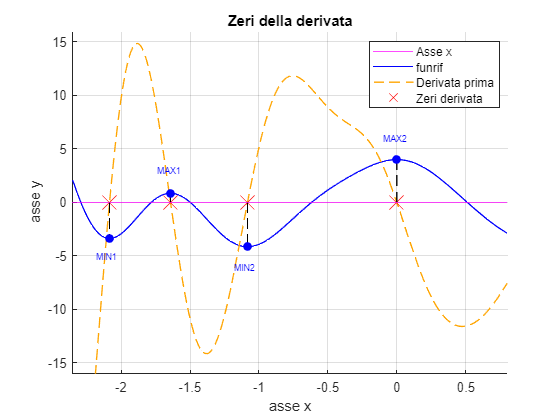

figure(9)
hold on
yline(0,'-','color','m') 
fplot(funrif,[a,b],'color','b')
fplot(derivataprima,[a,b],"--","LineWidth",1,'Color','#FFA500') 
plot([zeroder1 zeroder2 zeroder3 zeroder4],[0 0 0 0],'x','markersize',15,'color','red');%zeri derivata
legend({'Asse x','funrif','Derivata prima','Zeri derivata'},'Location','best','AutoUpdate','off')
axis([a b -16 16])  
grid on 
xlabel("asse x",'FontName','Arial')
ylabel("asse y",'FontName','Arial')
title("Zeri della derivata",'FontName','Arial')

%proiezione punti di min e max
plot([min1, min1], [0,funrif(min1)], '--','color','k')
plot([min2,min2], [0,funrif(min2)], '--','color','k')

plot([max1,max1],[funrif(max1),0],'--','color','k')
plot([max2,max2],[funrif(max2),0],'--','color','k')

%Indico le ascisse dei punti di minimo e di massimo
text(-2.18,-5,'MIN1', "Color", 'b',"FontSize",6.5);
text(-1.18,-6,'MIN2', "Color", 'b',"FontSize",6.5);
text(-1.74,3,'MAX1', "Color", 'b',"FontSize",6.5);
text(-0.1,6,'MAX2', "Color", 'b',"FontSize",6.5);

plot([zeroder1 zeroder2 zeroder3 zeroder4], [funrif(zeroder1) funrif(zeroder2) funrif(zeroder3) funrif(zeroder4) ],'o','color','b','MarkerFaceColor','b')%evidenzio i max e min

**Punto 9: determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due minimi, e il metodo di Golden search (nostra function **`fmingolden`**) per i due massimi, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette.**

Per usare* Fibonacci search *e il *Golden search* devo scegliere degli intervalli tali che la funzione risulti unimodale: cioè deve esistere un solo numero *r* in *[a,b]* tale che *f *è decrescente in *[a,r]* ed è crescente in *[r,b]*. Inoltre devo scegliere un delta_ass tale che sia uguale a 1e-3 per garantire la correttezza delle prime 3 cifre frazionarie.

Calcolo i minimi con *fminfibo*:

minfibo1=fminfibo(funrif,-2.3,-2,1e-3)%primo minimo

minfibo1 =   -2.082584269662921


minfibo2=fminfibo(funrif,-1.3,-1,1e-3)%secondo minimo

minfibo2 =   -1.082584269662922


Calcolo i massimi con *fmingolden* utilizzando la funzione inversa:

maxgolden1=fmingolden(inversa_funrif,-1.8,-1.4,1e-3)%primo massimo

maxgolden1 =   -1.641092976240432


maxgolden2=fmingolden(inversa_funrif,-0.1,0.1,1e-3)%secondo massimo

maxgolden2 =     -5.338882547861745e-16


**Punto 10:considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati.**

Approssimazioni Golden search:

errass_gold1=abs(maxgolden1-max1)%calcolo errore gold1

errass_gold1 =      2.112815702126625e-04


if errass_gold1<1e-3 %confronto con accuratezza scelta 
    fprintf('L''errore assoluto è minore dell''accuratezza richiesta.')
else
    fprintf('L''errore assoluto è maggiore dell''accuratezza richiesta.')
end

L'errore assoluto è minore dell'accuratezza richiesta.

errass_gold2=abs(maxgolden2-max2)%calcolo errore gold2

errass_gold2 =      1.042600348286228e-10


if errass_gold1<1e-3  %confronto con accuratezza scelta 
    fprintf('L''errore assoluto è minore dell''accuratezza richiesta.')
else
    fprintf('L''errore assoluto è maggiore dell''accuratezza richiesta.')
end

L'errore assoluto è minore dell'accuratezza richiesta.

Approssimazioni Fibonacci search:

errass_fibo1=abs(minfibo1-min1)%calcolo errore fibo1

errass_fibo1 =      9.622792977181938e-04


if errass_fibo1<1e-3  %confronto con accuratezza scelta 
    fprintf('L''errore assoluto è minore dell''accuratezza richiesta.')
else
    fprintf('L''errore assoluto è maggiore dell''accuratezza richiesta.')
end

L'errore assoluto è minore dell'accuratezza richiesta.

errass_fibo2=abs(minfibo2-min2)%calcolo errore fibo2

errass_fibo2 =      7.635992555101723e-04


if errass_fibo2<1e-3  %confronto con accuratezza scelta 
    fprintf('L''errore assoluto è minore dell''accuratezza richiesta.')
else
    fprintf('L''errore assoluto è maggiore dell''accuratezza richiesta.')
end

L'errore assoluto è minore dell'accuratezza richiesta.

In tutti e 4 i casi gli errori assoluti sono minori dell'accuratezza richiesta.